# Creating a simplifed version of an UAV resource allocation problem

## Simplified Model

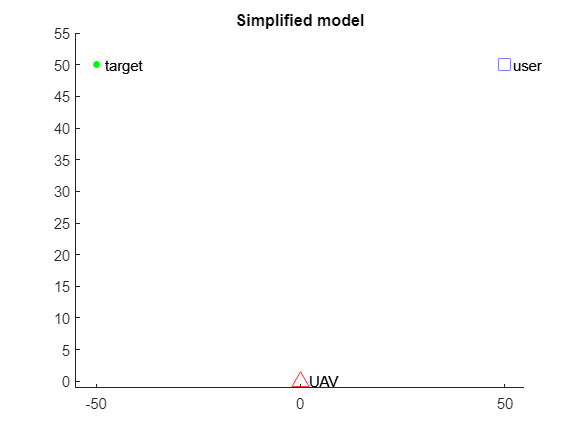

clearvars

UAV_pos = [0 0];
t_pos = [-50 50];
u_pos = [50 50];

% figure
scatter(UAV_pos(1), UAV_pos(2),100,'r','^')
hold on
scatter(t_pos(1), t_pos(2),200,'green','.')
scatter(u_pos(1), u_pos(2),100,'blue','s')
xlim([t_pos(1)-5 t_pos(2)+5])
ylim([-1 t_pos(2)+5])
% legend('UAV','Target','User','FontSize',5)
text(UAV_pos(1)+2, UAV_pos(2),'UAV')
text(t_pos(1)+2, t_pos(2),'target')
text(u_pos(1)+2, u_pos(2),'user')
title('Simplified model')

## Variables

N = 5; % # of time slots
h = repmat(diag([1 1]), 1,1,N); % channel matrix (no interference)
M = size(h,2);
P_max = 5; % hardware power limit
R_min = -100; % minimum rate
alt = 50;
a = zeros([1 N]); a(3)=1;

cvx_clear
cvx_begin
    variables W(size(h))
    expressions P_t(N) P_sense(N)

    P_total = 0;
    sv = steer_vec(UAV_pos, t_pos, M, alt);
    psi = (sqrt(norm(UAV_pos-t_pos)^2 + alt^2));

    for n=1:N
        P_t(n) = trace(W(:,:,n));
        P_total = P_total + P_t(n);
        P_sense(n) = a(n) * sv * P_t(n) * sv';
        P_comm(n) = (1-a(n)) * sv * P_t(n) * sv';
    end
    
    minimize (P_total)

    subject to
        0 <= P_t;
        P_t <= P_max;
        sum(P_sense) >= 2;
        sum(P_comm) >= 2;

cvx_end

 
Calling SDPT3 4.0: 27 variables, 7 equality constraints
------------------------------------------------------------

 num. of constraints =  7
 dim. of linear var  = 12
 dim. of free   var  = 15 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|5.7e+00|5.2e+01|1.1e+06|-1.318536e+02  0.000000e+00| 0:0:00| chol  1  1 
 1|0.948|0.984|3.0e-01|1.3e+00|5.4e+03|-1.409036e+01 -2.398902e+02| 0:0:00| chol  1  1 
 2|1.000|1.000|9.2e-08|1.5e-01|1.1e+02|-1.076712e+01 -3.278294e+01| 0:0:00| chol  1  1 
 3|0.904|1.000|2.7e-08|1.5e-02|2.1e+01|-2.083428e+01 -3.939086e+01| 0:0:00| chol  1  1 
 4|0.823|0.953